# `Loi de van der Waals et construction de Maxwell`

`On considère un fluide pouvant être décrit par l'équation d'état de Van der Waals dont la forme intensive est la suivante: `

`Veuillez commencer par rentrer les constantes du gaz étudié (ici, l'eau H2O): `

a = 5.237; % bar.L².mol-2
b = 0.0305; % L.mol-1

`Constantes utilisées par la suite`

%  Constante des gaz parfaits
R = 8.314; % J.mol-1.K-1 
% Température critique
T_c = 8 * a / (27 * b * R) % K

T_c = 6.1193

% Volume molaire critique
V_c = 3 * b % L.mol-1 

V_c = 0.0915

% Pression critique
P_c = a / (27 * b^2) % bar 

P_c = 208.5063

## `Loi de Van der Waals sans correction`

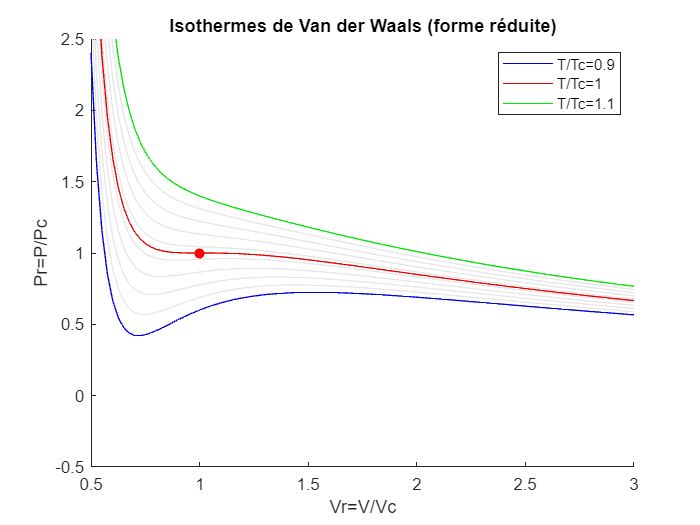

Vrmin = 0.5;
Vrmax = 3;

Vr = linspace(Vrmin, Vrmax, 100);

Trmin = 0.9;
Trmax = 1.1;

figure(1)
hold on

for Tr = linspace(Trmin, Trmax, 10)
    Pr = vanDerWaals_reduite_isothermes(Tr, Vr);
    plot(Vr, Pr, 'color', [.9 .9 .9])
end

Pr = vanDerWaals_reduite_isothermes(Trmin, Vr);
pmin = plot(Vr, Pr, 'color', [0 0 .9]);

Pr = vanDerWaals_reduite_isothermes(1, Vr);
pcrit = plot(Vr, Pr, 'color', [.9 0 0]);

Pr = vanDerWaals_reduite_isothermes(Trmax, Vr);
pmax = plot(Vr, Pr, 'color', [0 .9 0]);

scatter(1,1,'filled', 'red')

hold off

title('Isothermes de Van der Waals (forme réduite)')
xlim([Vrmin Vrmax])
ylim([-0.5 2.5])
xlabel('Vr=V/Vc')
ylabel('Pr=P/Pc')
legend([pmin, pcrit, pmax], {'T/Tc=0.9', 'T/Tc=1', 'T/Tc=1.1'})

Lorsque l'on trace les isothermes, on obtient que lorsque $$T \geq T_c $$, la courbe obtenue est bien monotone. Mais lorsque l'on a  $$T < T_c$
$, la pression oscille et on se retrouve à avoir par endroit $$\frac{\partial P}{\partial V} \geq 0$$, c'est-à-dire que la pression augmente lorsque le volume augmente ce qui ne correspond pas forcément aux observations expérimentales. 

## `Correction sur la loi de Van der Waals`

`On va utiliser la construction de Maxwell pour corriger la loi de Van der Waals. `

`(ptite explication de l'algorithme) `

Vrmin = 0.5;
Vrmax = 4;

Vr = linspace(Vrmin, Vrmax, 200);

Tr = 0.8;

figure(2)

[Vr_G, Vr_L, Pr_sat] = PalierMaxwell(Tr, 0.001)

Vr_G = 3.0234

Vr_L = 0.5134

Pr_sat = 0.4629

PrC = VDW_r_corrected_isothermes(Tr, Vr)

PrC =     0.8000    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629    0.4629


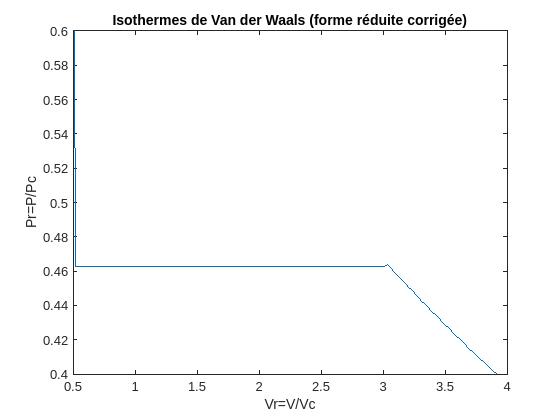

plot(Vr, PrC)

xlim([Vrmin Vrmax])
ylim([0.4 0.6])
xlabel('Vr=V/Vc')
ylabel('Pr=P/Pc')
title('Isothermes de Van der Waals (forme réduite corrigée)')

## `FONCTIONS UTILISEES`

`Loi de van der waals`

function [P] = vanDerWaals_isothermes(T,V)
% ============================= % 
% Renvoie la pression selon le volume molaire pour un gaz de Van der Waals 
% à une température donnée. 
% ============================= % 
% Paramètres : 
% T (float) : Température en Kelvin du gaz
% V (array) : Volume molaire en L/mol
% ============================= % 
% Retours : 
% P (array) : Pression du gaz en Bar
% ============================= %
    P = R * T ./ (V - b) - a ./ (V.*V);
end


Loi de Van der Waals réduite 

function [Pr] = vanDerWaals_reduite_isothermes(Tr,Vr)
% ============================= % 
% Renvoie la pression réduite selon le volume molaire réduit pour un gaz de Van 
% der Waals à une température donnée. 
% ============================= % 
% Paramètres : 
% T (float) : Température réduite (sans dimension)
% V (array) : Volume molaire réduit
% ============================= % 
% Retours : 
% P (array) : Pression réduite du gaz (sans dimension)
% ============================= %

    Pr = 8 * Tr ./ (3 * Vr - 1) - 3 ./ (Vr.*Vr);
end


Construction de Maxwell - Règle du palier

function [Vr_G, Vr_L, Pr_sat] = PalierMaxwell(Tr, epsilon)
% ============================= % 
% Renvoie les volumes molaires réduits de la phase gaz
% et liquide, ainsi que la pression saturante réduite
% pour une température réduite donnée. 
% ============================= % 
% Paramètres : 
% T (float) : Température réduite (sans dimension)
% ============================= % 
% Retours : 
% Vr_G (float) : Volume molaire phase gaz réduit (sans dimension)
% Vr_L (float) : Volume molaire phase liquide réduit (sans dimension)
% Pr_sat (float) : Pression saturante réduite (sans dimension)
% ============================= %
    
    delta = 1;
    % Initialisation
    Pmin = 0;
    Pmax = 1;
    P0 = 0.5;
    R = 8.314;

    while abs(delta) > epsilon
        %   --> Coefficients du polynôme de compressibilité
        a0 = - P0^2 / (Tr^3 * R^3);
        a1 = (3 * P0) / (R^2 * Tr^2);
        a2 = -(P0 / (3 * R * Tr) + 8/(3 * R));
        a3 = 1;
        %   --> Recherche des racines
        r = roots([a3 a2 a1 a0]);
        % Raisonnement par dichotomie
        % Si il y a une racine  réelle et deux complexes Psat > P0
        if isreal(r)
            Vr_L = min(r) * R * Tr / P0;
            Vr_G = max(r) * R * Tr / P0;
            delta = getDeltaR(Vr_G, Vr_L, P0, Tr);
            % Si il y en a 3 on calcule le delta 
            if delta > 0
                Pmin = P0;
                P0 = (P0 + Pmax) / 2;
            elseif delta < 0
                Pmax = P0;
                P0 = (P0 + Pmin) / 2;
            end
        else
            P0 = Pmin + rand * (Pmax - Pmin);
        end
    end
    Pr_sat = P0;
end

% === Calcul de la différence d'aire === %

function [deltaR] = getDeltaR(Vr_G, Vr_L, P0, Tr)
    deltaR = 8 * Tr * log((3 * Vr_G)/(3 * Vr_L - 1)) / 9;
    deltaR = deltaR - (Vr_G - Vr_L)/(Vr_G * Vr_L);
    deltaR = deltaR - P0 * (Vr_G - Vr_L) / 3;
end


function [Pr] = VDW_r_corrected_isothermes(Tr,Vr)
% ============================= % 
% Renvoie la pression réduite selon le volume molaire réduit pour un gaz de Van 
% der Waals à une température donnée. 
% ============================= % 
% Paramètres : 
% Tr (float) : Température réduite (sans dimension)
% Vr (array) : Volume molaire réduit
% ============================= % 
% Retours : 
% Pr (array) : Pression réduite du gaz (sans dimension)
% ============================= %

    % Si on est au dessus de la temp critique on applique la loi non
    % corrigée
    if Tr >= 1
        Pr = 8 * Tr ./ (3 * Vr - 1) - 3 ./ (Vr.*Vr);
    else
        [Vr_G, Vr_L, Pr_sat] = PalierMaxwell(Tr, 0.0001);
        Pr = 1:1:length(Vr);
        for i = 1:1:length(Vr)
            % On vérifie que l'on est entre V_L et V_G
            if Vr(i) >= Vr_L && Vr(i) <= Vr_G
                Pr(i) = Pr_sat;
            % Sinon on applique la loi non corrigée
            else
                Pr(i) = 8 * Tr / (3 * Vr(i) - 1) - 3 / (Vr(i)^2);
            end
        end
    end
end
